## IV Praktikum 2022

### Vorbereitungsteil:

#### Aufgabe 1


$$|E| = \frac{1}{\sqrt2} 1V,
 $$
 
$$R_1=R_2=R=50 \Omega$$


#### 1. Bestimmen Sie Pmax. 

 
$$P_{max} = \frac{|E|^2}{4R}$$
    


$$|E|^2 = \left( \frac{1V} {\sqrt{2}} \right)^2$$
 
$$ \Rightarrow  $$
   
$$|E|^2 = \frac{1}{2}V^2
$$


$P_{max} = \frac{\frac{1V^2}{2}}{4R} = \frac{1V^2}{8R} = \frac 1 {400}  \frac {V^2} \Omega
$ $=2,5
$mW  

syms R E
P_max = abs(E)^2/(4*R)

$$P\_max = \frac{{\left|\text{E}\right|}^{2}}{4\,R}$$

P_max = double(subs(P_max,[E,R],[1/sqrt(2),50]))*1000  %W --> mW

P_max = 2.5000

#### 2. Bestimmen Sie S21(jω).


$$S_{21} = k \frac {U_2} E = 2 \sqrt \frac{R_1} {R_2} \frac {U_2} {U_1} \frac{U_1} {E}$$
  
$$\Rightarrow$$
 
$$S_{21} = 2 \frac {U_2} E$$



$$U_2 = I * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \\
I = \frac E {R_{ges}}$$
  
$$\Rightarrow$$
 
$$U_2 = \frac E {R_{ges}} * \left( R_2+ \frac 1 {j\omega C} \right)^{-1} \rightarrow  S_{21} = 2 \frac { \left( R_2+ \frac 1 {j\omega C} \right)^{-1}} {R_{ges}}$$



$$R_{ges} =  R + C||R \\
C||R = \frac1 {j \omega C+\frac 1 R}$$
        
$$\Rightarrow
$$
     
$$R_{ges} = R + \frac 1 {j \omega C + \frac 1 R}$$
  


$$S_{21} = 2 \frac { \left( \frac 1 R+ j\omega C \right)^{-1}} {R+ \frac R {j \omega C R + 1}} $$


syms R omega C real
R_ges = R + 1/(1i*omega*C+1/R);
S_21 = 2*((1/R+1i*omega*C)^-1)/(R+R/(1+1i*omega*C*R)) %2*R/R_ges

$$S\_21 = \frac{2}{\left(\frac{1}{R}+C\,\omega \,\mathrm{i}\right)\,\left(R+\frac{R}{1+C\,R\,\omega \,\mathrm{i}}\right)}$$

simplify(S_21,"Steps",640)

$$ans = \frac{2}{2+C\,R\,\omega \,\mathrm{i}}$$

#### 3. Bestimmen Sie |S21(jω)|² und AdB(ω).

simplify(abs(S_21)^2,"Steps",100)

$$ans = \frac{4\,R^{2}\,{\left|C\,R\,\omega -\mathrm{i}\right|}^{2}}{{\left|C\,R\,\omega -2\,\mathrm{i}\right|}^{2}\,{\left|1+C\,R\,\omega \,\mathrm{i}\right|}^{2}\,{\left|R\right|}^{2}}$$

S21 = 4/(C^2*R^2*omega^2 + 4) - (2i*C*R*omega)/(C^2*R^2*omega^2 + 4)

$$S21 = \frac{4}{C^{2}\,R^{2}\,\omega^{2}+4}-\frac{2\,C\,R\,\omega \,\mathrm{i}}{C^{2}\,R^{2}\,\omega^{2}+4}$$

simpS21_abs_quad = (4*C^2*R^2*omega^2)/(C^2*R^2*omega^2 + 4)^2 + 16/(C^2*R^2*omega^2 + 4)^2

$$simpS21\_abs\_quad = \frac{16}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}+\frac{4\,C^{2}\,R^{2}\,\omega^{2}}{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}$$

A_db = 10*log10((C^2*R^2*omega^2 + 4)^2/(4*C^2*R^2*omega^2+16))

$$A\_db = \frac{10\,\log\left(\frac{{\left(C^{2}\,R^{2}\,\omega^{2}+4\right)}^{2}}{4\,C^{2}\,R^{2}\,\omega^{2}+16}\right)}{\log\left(10\right)}$$

simA_db = simplify(A_db,"Steps",100)

$$simA\_db = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

#### 4. Zeichnen Sie AdB(ω) qualitativ. 

A_dB = symfun(simA_db,[C,R,omega])

$$A\_dB(C, R, omega) = \frac{10\,\log\left(\frac{C^{2}\,R^{2}\,\omega^{2}}{4}+1\right)}{\log\left(10\right)}$$

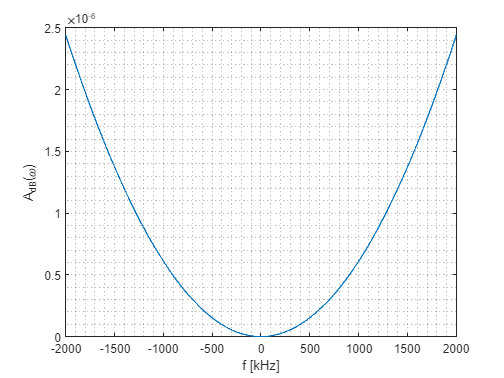

plot(-2000:10:2000,A_dB(15*10^-9,50,-2000:10:2000)) %C-Wert aus letzte Aufgabe
xlabel ("f [kHz]")
ylabel("A_{dB}(\omega)")
grid("minor")

#### 5. Handelt es sich um ein Hochpass- oder ein Tiefpassfilter? Begründen Sie Ihre Antwort.

Tiefpass, da tiefe Frequ. eine geringe Dämpfung haben und hohe Freq. eine hohe Dämpfung.

#### 6. Bestimmen Sie C in Abhängigkeit von der Durchlasskreisfrequenz $\omega_g$ und dem Rippel im Durchlassbereich $A_D$. Nutzen Sie dazu den Ansatz $A_{dB}(\omega_g) = A_D$. 

syms A_D
formula = solve(simA_db==A_D,C,"ReturnConditions",true);
formula.C(2)

$$ans = \frac{2\,\sqrt{10^{A_{D}/10}-1}}{R\,\omega }$$

#### 7. Bestimmen Sie den Wert von C für $f_g = 100kHz$ und $A_D = 0.28dB$. Runden Sie Ihr Ergebnis auf den nächsten in der E6-Bauteilreihe1 verfugbaren Wert.

double(subs(formula.C(2),[A_D R omega], [0.28 50 2*pi*10^5]))*10^9  %%F --> nF

ans = 16.4288

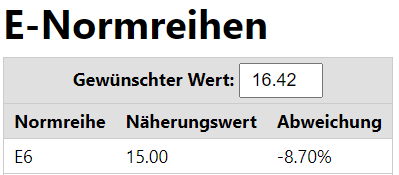

C_value = 15 %nF

C_value = 15

Kondensator: $X_c = \frac 1 {j \omega C}$ mit $\omega = 2\pi f$ 


$$f_g = \frac 1 {2 \pi R C}$$


fg = 1/(1i*2*pi*R*C)
A_dB
double(subs(A_dB,omega,2*pi*fg))




C = 16.4 nF

Vorgehensweiße:

Aufgabe 8:

Zuerst muessen die Vorgegeben Werte auf dem Generator einigestellt werden. 100kHz und 1V:

Beim Anschalten des Ozsi. wird das Signal mit dem Auto-Detect Knopf detektiert. Fuer die Ablesung der Amplitude muss noch vertikal rein gezoomt werden.

Die Amplitude hatte ein Wert von 58.8 mW (siehe Screenshot). 

Aufgabe 9

Amplitude 58.8

Perdiodendauer ist 10 mikro Sekunde

f = [10 50 90 100 150 170 180 200 300 500 1000 2000]

ans =           10          50          90         100         150         170         180         200         300         500        1000        2000


Amplidtude = [506 498]
Periodendauer = [104 ]


f = linspace(0,1,10000)

f =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


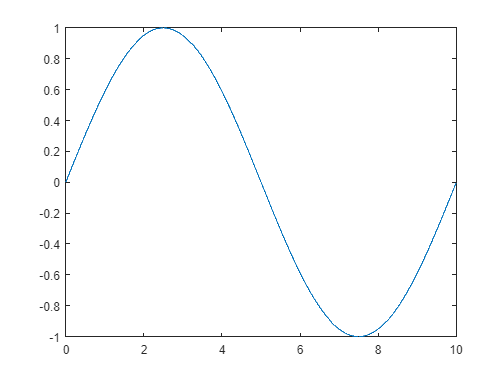

plot(1/1000:1/1000:10,sin(2*pi*f))

## Aufgabe 2

- $\Omega_s < 2$  --> n=3 (siehe Filtertabelle)

- 
$$\Theta = 30$$
 
$$r_1 = r_2 = 1$$
